# Post processing

## Read futek data

% should add out folder to matlab path
fds = fileDatastore('futek_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
futek_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_futek_data(fullFileNames{k});
    if isempty(A) == false
        futek_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        futek_data{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_map_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_map_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_multiroll.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_press_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_press_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s1.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s2.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s3.txt
Now 

## Read velostat data

fds = fileDatastore('velostat_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
velostat_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_velostat_data(fullFileNames{k});
    if isempty(A) == false
        velostat_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        velostat_data{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_map_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_map_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_multiroll.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_press_b.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_press_s.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s1.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s2.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data

## Take needed data

%same order
% needed_futek_num=[2]';
% needed_velostat_num = [2]';
% futek_data = futek_data(needed_futek_num,:);
% velostat_data = velostat_data(needed_velostat_num,:);

% receive a mat of values from futek, 1 file
% cur_mat = cell2mat(velostat_data{1,1}(:,1));

## Experiment 1, repitability

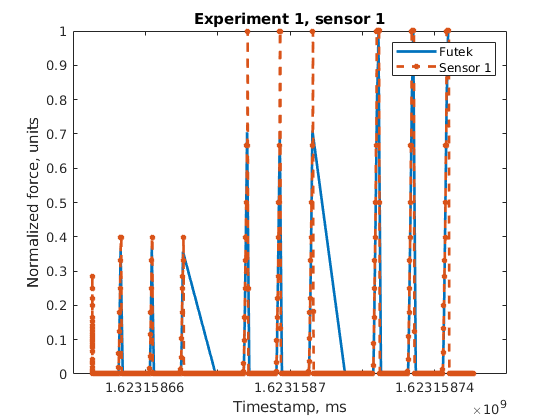

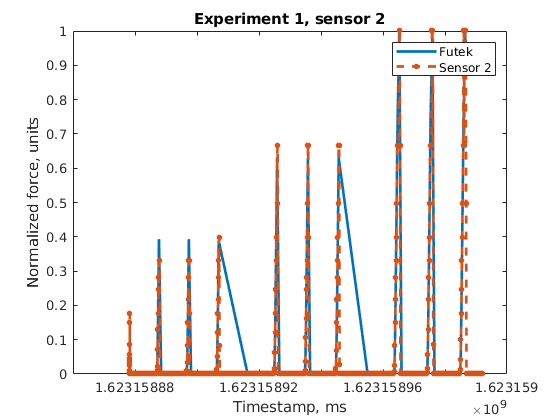

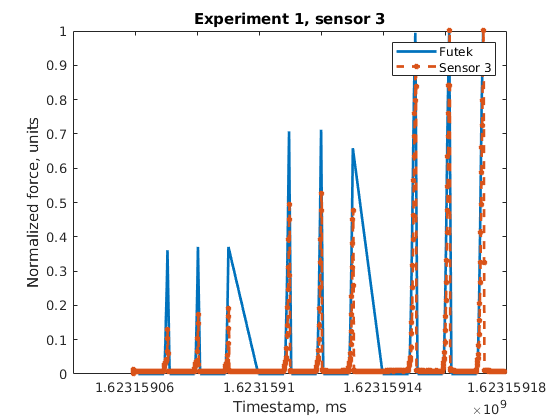

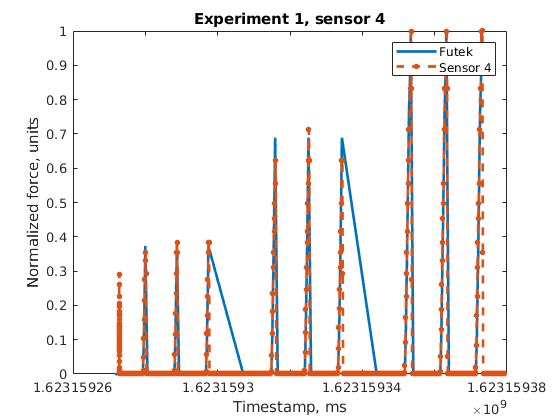

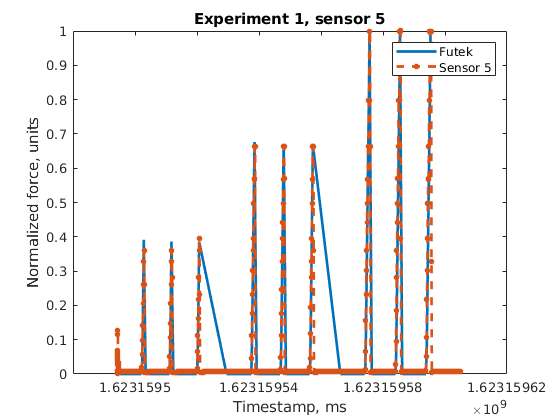

num = (7:11);
exp1_futek_data = futek_data(num,:);
exp1_velostat_data = velostat_data(num,:);

for i = 1:length(num)
    figure
    xa = cell2mat(exp1_futek_data{i,1}(:,2));
    ya = norm_data(cell2mat(exp1_futek_data{i,1}(:,1)));
    xb = cell2mat(exp1_velostat_data{i,1}(:,2));
    yb = norm_data(cell2mat(exp1_velostat_data{i,1}(:,1)));
    cur_plot = plot(xa,ya,xb,yb);
    title("Experiment 1, sensor " + i);
    xlabel("Timestamp, ms");
    ylabel("Normalized force, units");
    legend("Futek","Sensor " + i);
    cur_plot(1).LineWidth = 2;
    cur_plot(2).LineWidth = 2;
    cur_plot(2).LineStyle = '--';
    cur_plot(2).MarkerSize= 4;
    cur_plot(2).Marker = "*";
end

disp("TODO statistics")

TODO statistics


## Experiment 2, pressure vs Force

num = (5:6);
exp2_futek_data = futek_data(num,:);
exp2_velostat_data = velostat_data(num,:);
sens_text = ["big", "small"];

sens_text = 1×2 string array
    "big"    "small"


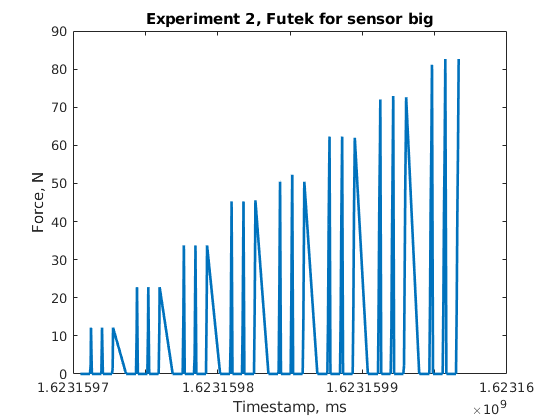

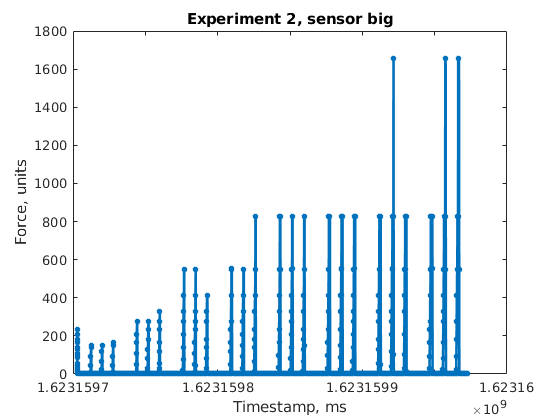

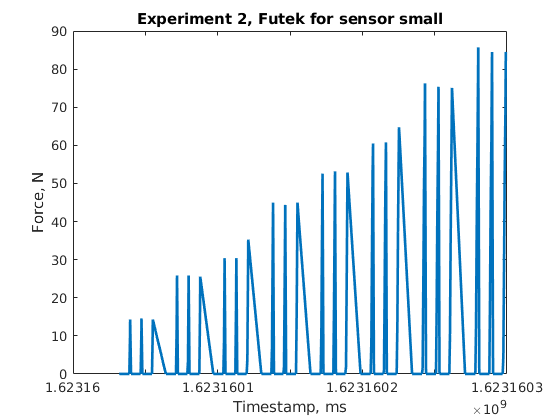

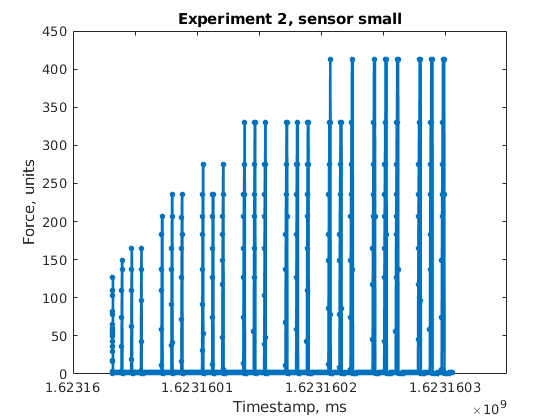


for i = 1:length(num)
    xa = cell2mat(exp2_futek_data{i,1}(:,2));
    ya = cell2mat(exp2_futek_data{i,1}(:,1));
    xb = cell2mat(exp2_velostat_data{i,1}(:,2));
    yb = cell2mat(exp2_velostat_data{i,1}(:,1));
    
    figure
    cur_plot = plot(xa,ya);
    title("Experiment 2, Futek for sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Force, N");
    cur_plot(1).LineWidth = 2;
    
    figure
    cur_plot = plot(xb,yb);
    title("Experiment 2, sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Force, units");
    cur_plot(1).LineWidth = 2;
    cur_plot(1).MarkerSize= 4;
    cur_plot(1).Marker = "*";
end

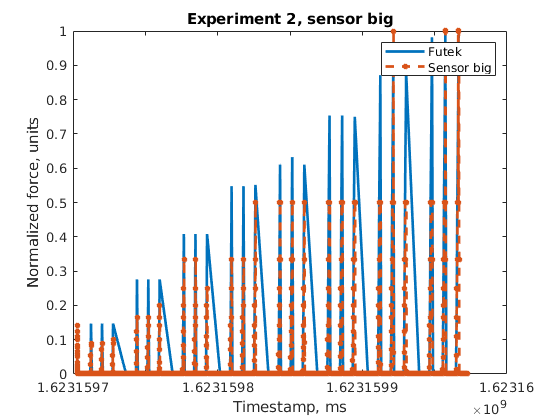

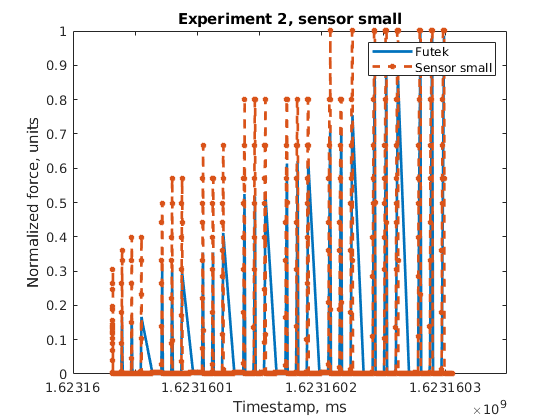


for i = 1:length(num)
    figure
    xa = cell2mat(exp2_futek_data{i,1}(:,2));
    ya = norm_data(cell2mat(exp2_futek_data{i,1}(:,1)));
    xb = cell2mat(exp2_velostat_data{i,1}(:,2));
    yb = norm_data(cell2mat(exp2_velostat_data{i,1}(:,1)));
    cur_plot = plot(xa,ya,xb,yb);
    title("Experiment 2, sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Normalized force, units");
    legend("Futek","Sensor " + sens_text(i));
    cur_plot(1).LineWidth = 2;
    cur_plot(2).LineWidth = 2;
    cur_plot(2).LineStyle = '--';
    cur_plot(2).MarkerSize= 4;
    cur_plot(2).Marker = "*";
end

disp("TODO statistics")

TODO statistics


## Experiment 3, sensor force map

val =   137.0000
  330.2000
  413.0000
  551.0000
  275.0000
  275.0000
  413.0000
  413.0000
  275.1667
  275.0000


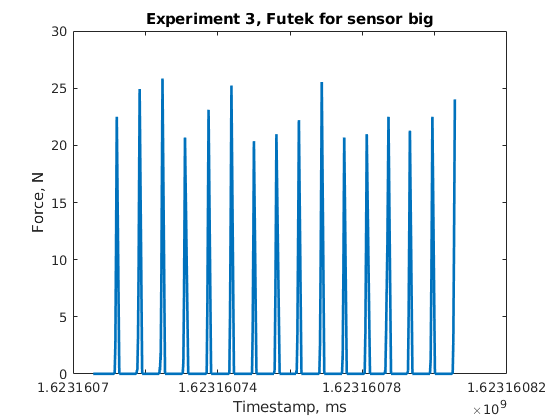

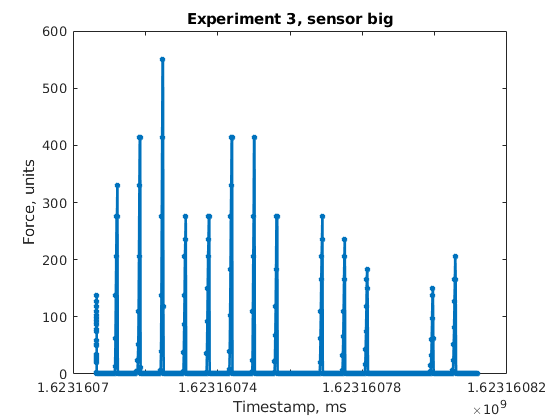

val =   235.5714
  235.7143
  275.1667
  235.5714
  126.4615
  183.0000
  149.6364
  164.6000
  149.5455
  183.0000


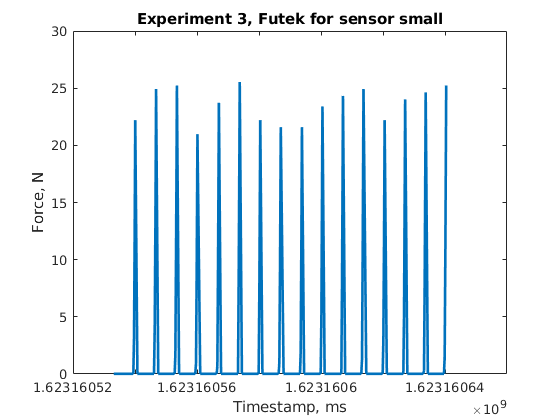

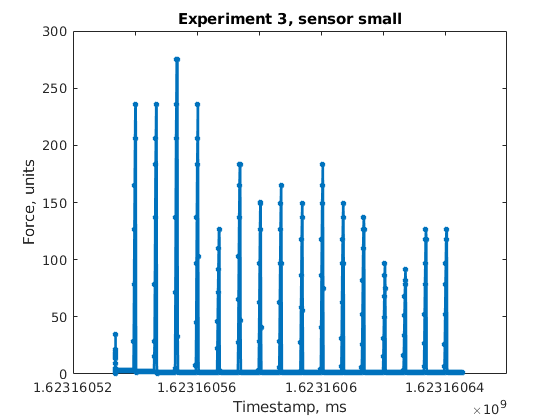

num = (2:3);
exp3_futek_data = futek_data((num),:);
exp3_velostat_data = velostat_data((num),:);
sens_text = ["big", "small"];

for i = 1:length(num)
    xa = cell2mat(exp3_futek_data{i,1}(:,2));
    ya = cell2mat(exp3_futek_data{i,1}(:,1));
    xb = cell2mat(exp3_velostat_data{i,1}(:,2));
    yb = cell2mat(exp3_velostat_data{i,1}(:,1));
    [val,~] = findpeaks(yb,"MinPeakHeight",40,"MinPeakDistance",50)
    
    figure
    cur_plot = plot(xa,ya);
    title("Experiment 3, Futek for sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Force, N");
    cur_plot(1).LineWidth = 2;
    
    figure
    
    cur_plot = plot(xb,yb);
    title("Experiment 3, sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Force, units");
    cur_plot(1).LineWidth = 2;
    cur_plot(1).MarkerSize= 4;
    cur_plot(1).Marker = "*";
end

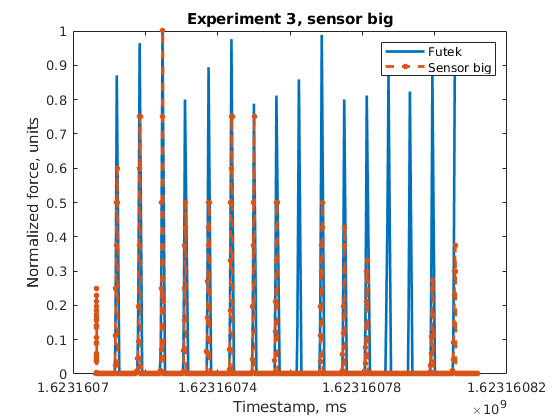

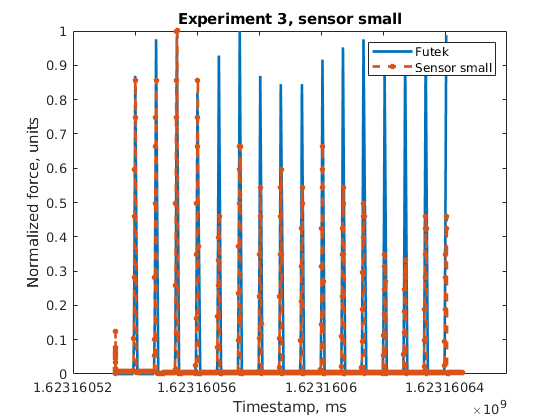


for i = 1:length(num)
    figure
    xa = cell2mat(exp3_futek_data{i,1}(:,2));
    ya = norm_data(cell2mat(exp3_futek_data{i,1}(:,1)));
    xb = cell2mat(exp3_velostat_data{i,1}(:,2));
    yb = norm_data(cell2mat(exp3_velostat_data{i,1}(:,1)));
    cur_plot = plot(xa,ya,xb,yb);
    title("Experiment 3, sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Normalized force, units");
    legend("Futek","Sensor " + sens_text(i));
    cur_plot(1).LineWidth = 2;
    cur_plot(2).LineWidth = 2;
    cur_plot(2).LineStyle = '--';
    cur_plot(2).MarkerSize= 4;
    cur_plot(2).Marker = "*";
end

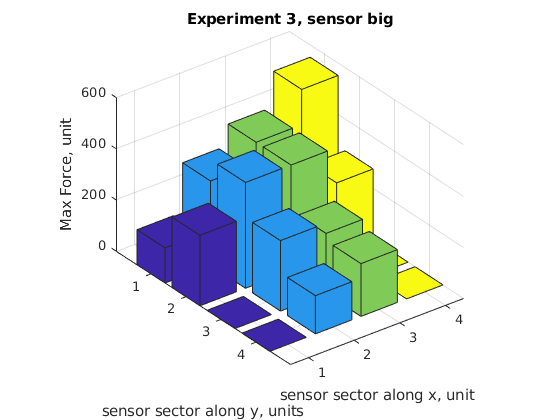


figure
Zb = [[137,330,413,551];[275,413,413,275];[0,275,235,0];[0,149,206,0]];
Zs = [[235,235,275,235];[126,183,149,164];[149,183,149,126];[96,91,126,126]];
bar3(Zb);
title("Experiment 3, sensor big");
xlabel("sensor sector along x, unit");
ylabel("sensor sector along y, units");
zlabel("Max Force, unit")

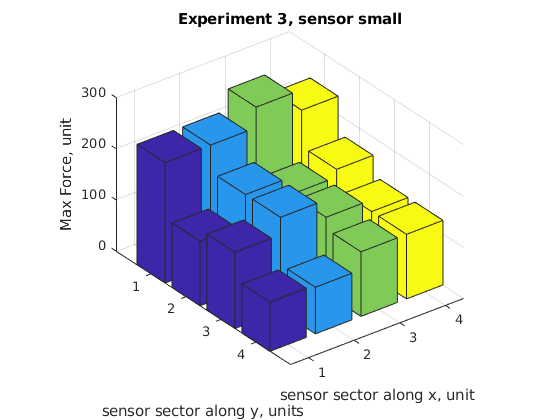

figure
bar3(Zs);
title("Experiment 3, sensor small");
xlabel("sensor sector along x, unit");
ylabel("sensor sector along y, units");
zlabel("Max Force, unit")


disp("TODO statistics")

TODO statistics


## Experiment 4, leg load simulation (rolling rolls)

num = (4);
exp4_futek_data = futek_data(num,:);
exp4_velostat_data = velostat_data(num,:);
sens_text = ["big", "small"];

for i = 1:length(num)
    xa = cell2mat(exp4_futek_data{i,1}(:,2));
    ya = cell2mat(exp4_futek_data{i,1}(:,1));
    xb = cell2mat(exp4_velostat_data{i,1}(:,2));
    yb = cell2mat(exp4_velostat_data{i,1}(:,1));
    
    figure
    cur_plot = plot(xa,ya);
    title("Experiment 4, Futek for sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Force, N");
    cur_plot(1).LineWidth = 2;
    
    figure
    cur_plot = plot(xb,yb);
    title("Experiment 4, sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Force, units");
    cur_plot(1).LineWidth = 2;
    cur_plot(1).MarkerSize= 4;
    cur_plot(1).Marker = "*";
end

for i = 1:length(num)
    figure
    xa = cell2mat(exp4_futek_data{i,1}(:,2));
    ya = norm_data(cell2mat(exp4_futek_data{i,1}(:,1)));
    xb = cell2mat(exp4_velostat_data{i,1}(:,2));
    yb = norm_data(cell2mat(exp4_velostat_data{i,1}(:,1)));
    cur_plot = plot(xa,ya,xb,yb);
    title("Experiment 4, sensor " + sens_text(i));
    xlabel("Timestamp, ms");
    ylabel("Normalized force, units");
    legend("Futek","Sensor " + sens_text(i));
    cur_plot(1).LineWidth = 2;
    cur_plot(2).LineWidth = 2;
    cur_plot(2).LineStyle = '--';
    cur_plot(2).MarkerSize= 4;
    cur_plot(2).Marker = "*";
end
disp("TODO statistics")

% plot(cell2mat(experimenttestsensor3v(:,2)),norm_data(cell2mat(experimenttestsensor3v(:,1))),'DisplayName','ans')
% plot(cell2mat(experimenttestsensor2v(:,2)),norm_data(cell2mat(experimenttestsensor2v(:,1))),'DisplayName','ans')
% plot(cell2mat(experimenttestsensorv(:,2)),norm_data(cell2mat(experimenttestsensorv(:,1))),'DisplayName','ans')

